# EE114 Coding Assignment II

# Name: Buddy Ugwumba SID: 862063029

## 1. Random Points Over a Square

- Plot the distribution of X

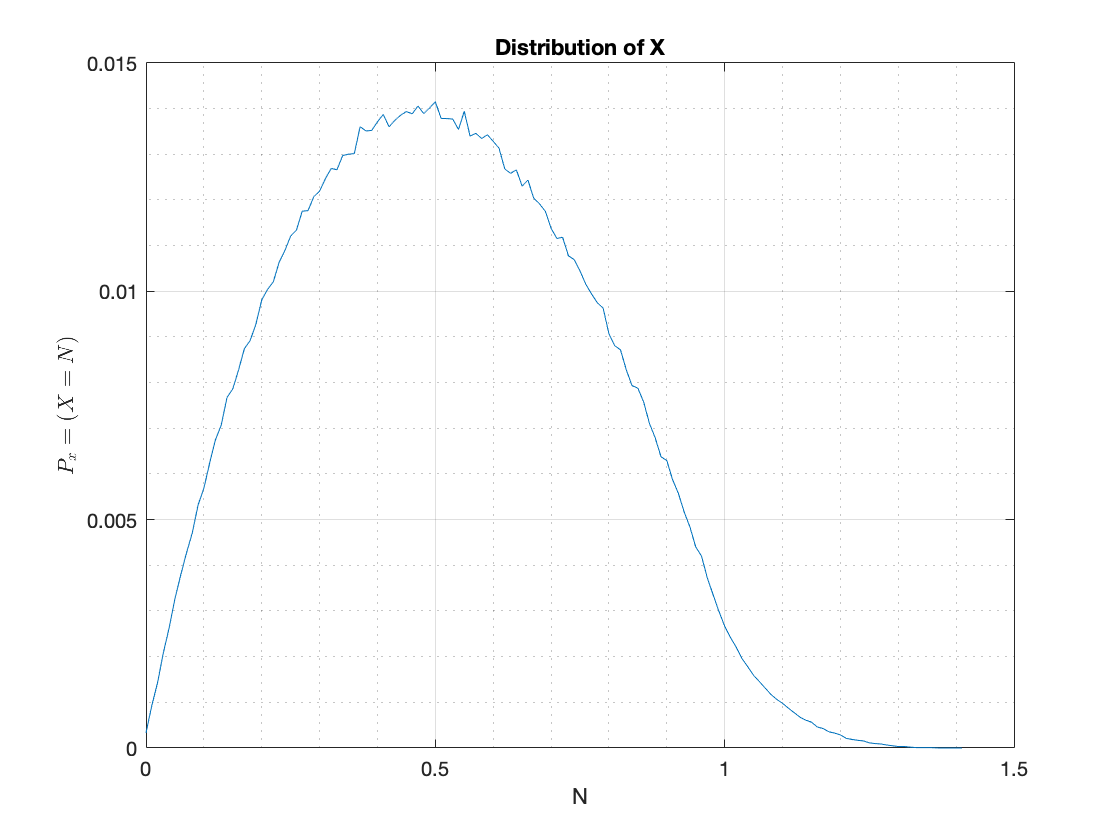

N = 1000000;
% Generate random points
P_1 = rand(N,2);
P_2 = rand(N,2);
X_1 = P_1(:,1);
Y_1 = P_1(:,2);
X_2 = P_2(:,1);
Y_2 = P_2(:,2);

% Calculate the Euclidean distance
big_X = ((X_1 - X_2).^(2) + (Y_1 - Y_2).^(2)).^(1/2);
count = 0:0.01:sqrt(2);
counter = 1;
pointer = 1;
numelements = 0;
values = ones(1,1);

%Calculate Distribution of X
while counter <= length(count)
    for c = 1:1:N
        if big_X(c) >= count(pointer) && big_X(c) <= count(pointer+1)
            numelements = numelements +1;
        end
    end
    numelements = numelements/N;
    values(counter)=numelements;
    if pointer ~= length(count)
        pointer=pointer+1;        
    end
    counter = counter+1;
    numelements=0;
end
plot(count,values)
grid on
grid minor
title('Distribution of X');
xlabel('N');
ylabel('$$P_{x} = (X = N) $$', 'Interpreter', 'latex');

2. Plot $P_N$as a function of $N$for $1\le N\le 1,000,000$

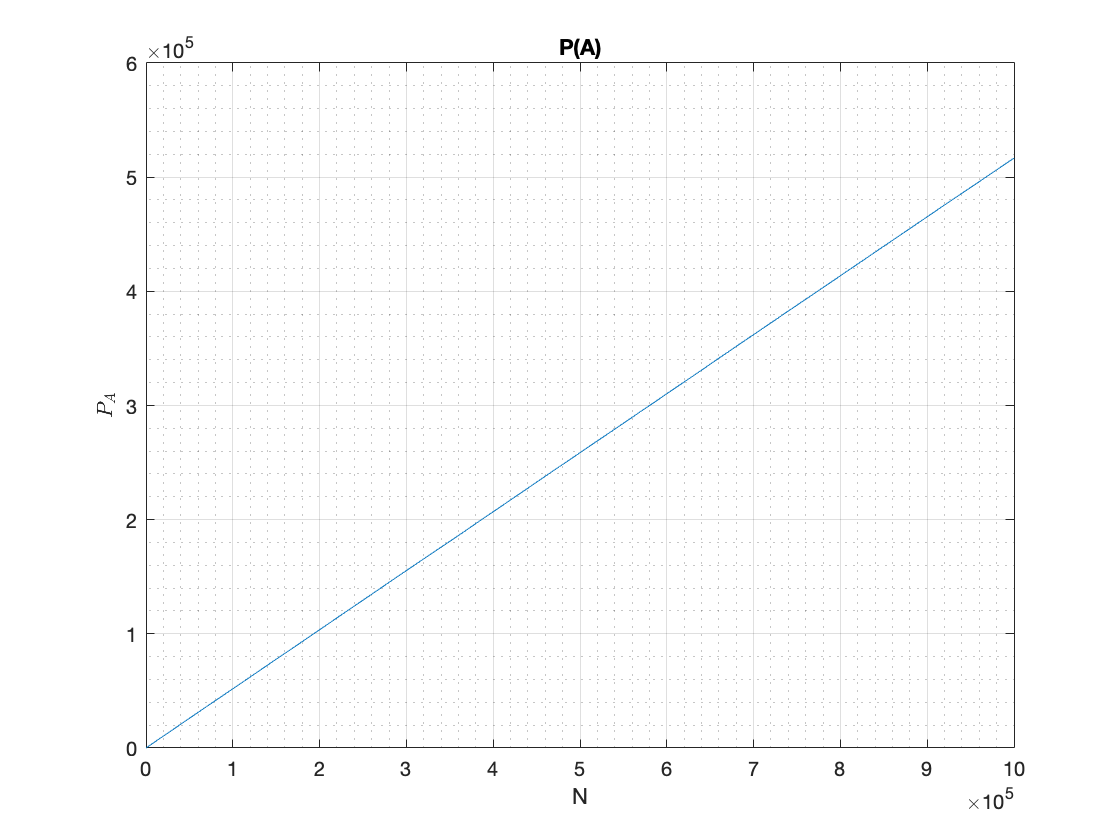

pos = 0;
holder = zeros(1,1);
for c = 1:1:N
    if big_X(c) >= 0.5
        pos = pos+1;
    end
    holder(c) = pos;
end
N_interval = 1:1:N;
plot(N_interval,holder);
grid on
grid minor
title('P(A)');
xlabel('N');
ylabel('$$P_{A}$$', 'Interpreter', 'latex');

## 2. Three Random Points Over a Cube

- Plot the distribution of X

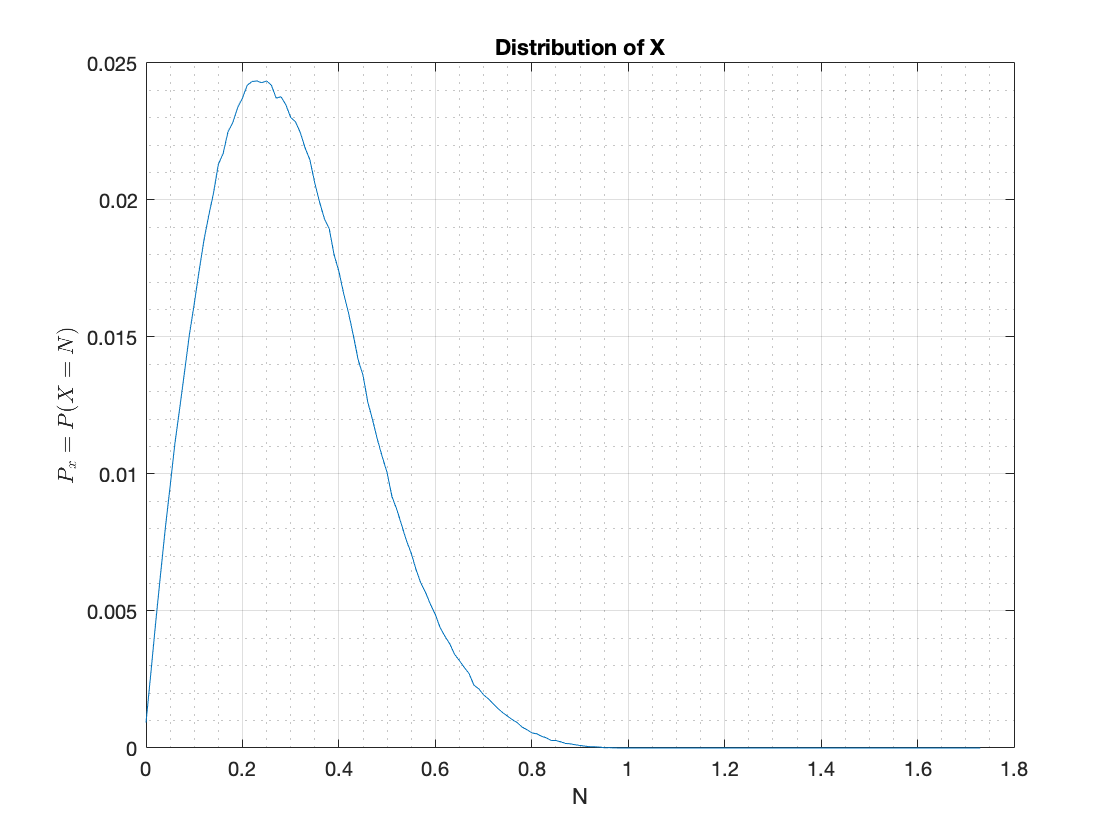

% Generate 3 independent random points
P_1 = rand(N,2);
P_2 = rand(N,2);
P_3 = rand(N,2);
X_1 = P_1(:,1);
Y_1 = P_1(:,2);
X_2 = P_2(:,1);
Y_2 = P_2(:,2);
X_3 = P_3(:,1);
Y_3 = P_3(:,2);

big_a = ((X_1 - X_2).^(2) + (Y_1 - Y_2).^(2)).^(1/2);
big_b = ((X_1 - X_3).^(2) + (Y_1 - Y_3).^(2)).^(1/2);
big_c = ((X_2 - X_3).^(2) + (Y_2 - Y_3).^(2)).^(1/2);

big_X = cat(N,big_a,big_b,big_c);
big_X = min(big_X,[],N);
count = 0:0.01:sqrt(3);
counter = 1;
pointer = 1;
numelements = 0;
values = ones(1,1);

%Calculate Distribution of X
while counter <= length(count)
    for c = 1:1:N
        if big_X(c) >= count(pointer) && big_X(c) <= count(pointer+1)
            numelements = numelements +1;
        end
    end
    numelements = numelements/N;
    values(counter)=numelements;
    if pointer ~= length(count)
        pointer=pointer+1;        
    end
    counter = counter+1;
    numelements=0;
end
plot(count,values)
grid on
grid minor
title('Distribution of X');
xlabel('N');
ylabel('$$P_{x} = P(X = N)$$', 'Interpreter', 'latex');

2. Plot $P_N$as a function of $N$for $1\le N\le 1,000,000$

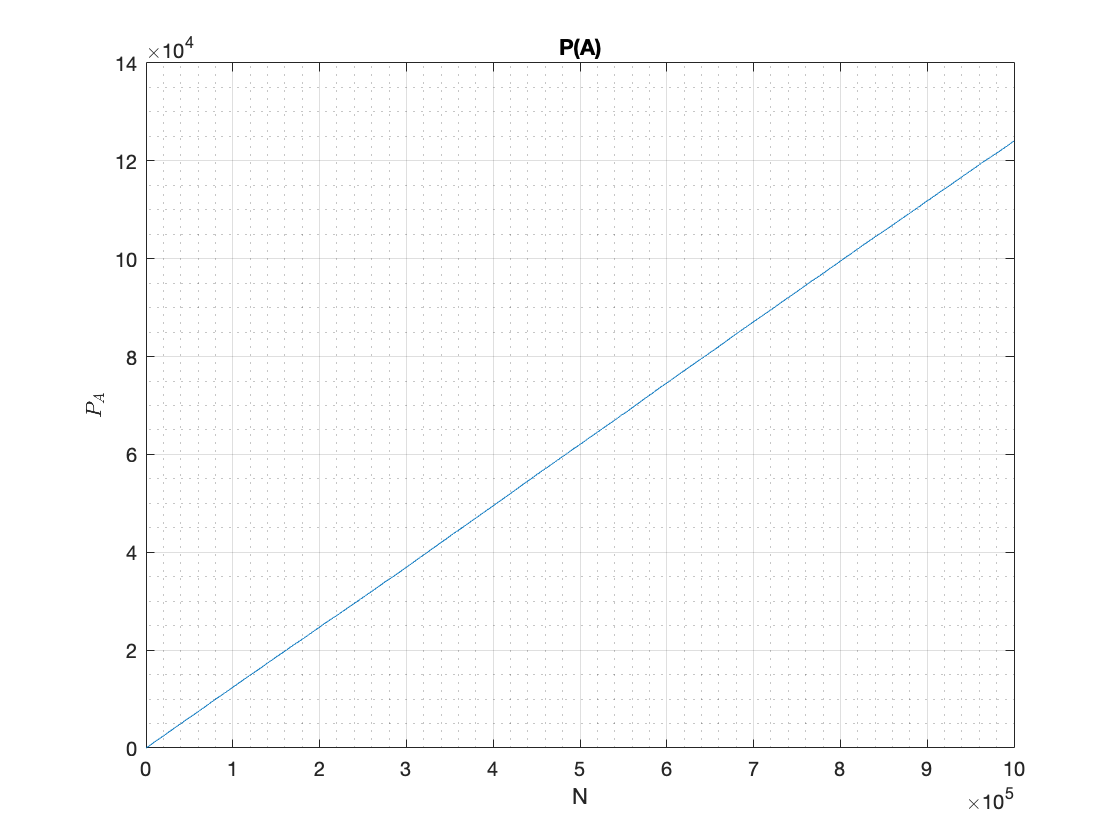

holder = ones(1,1);
pos = 1;
for c = 1:1:N
    if big_X(c) >= 0.5
        pos = pos +1;
    end
    holder(c) = pos;
end
plot(N_interval,holder)
grid on
grid minor
title('P(A)');
xlabel('N');
ylabel('$$P_{A}$$', 'Interpreter', 'latex');

## 3. Volume of a Simplex

% When d = 1
simp = rand(N, 1);
y = 0;
D1 = simp(:,1);
for c = 1:1:N
    if D1(c) <= 1
        y = y+1;
    end
end
prob = y/N

prob = 1


% When d = 2
y = 0;
simp2 = rand(N, 2);
point1 = simp2(:,1);
point2 = simp2(:,2);
D2 = point1 + point2;
for c = 1:1:N
    if D2(c) <= 1
        y = y+1;
    end
end
prob = y/N 

prob = 0.5012


% When d = 3
y = 0;
simp3 = rand(N, 3);
point1 = simp3(:,1);
point2 = simp3(:,2);
point3 = simp3(:,3);
D3 = point1 + point2 + point3;
for c = 1:1:N
    if D3(c) <= 1
        y = y+1;
    end
end
prob = y/N 

prob = 0.1672


%when d = 4
y = 0;
simp4 = rand(N, 4);
point1 = simp4(:,1);
point2 = simp4(:,2);
point3 = simp4(:,3);
point4 = simp4(:,4);
D4 = point1 + point2 + point3 + point4;
for c = 1:1:N
    if D4(c) <= 1
        y = y+1;
    end
end
prob = y/N 

prob = 0.0421


% When d = 5
simp5 = rand(N, 5);
y = 0;
simp3 = rand(N, 3);
point1 = simp5(:,1);
point2 = simp5(:,2);
point3 = simp5(:,3);
point4 = simp5(:,4);
point5 = simp5(:,5);
D5 = point1 + point2 + point3 + point4 + point5;
for c = 1:1:N
    if D5(c) <= 1
        y = y+1;
    end
end
prob = y/N 

prob = 0.0084

Yes, I do believe that there is an analytical formula for $\mathrm{Vol}\left(S\right)$ and that formula is $\mathrm{Vol}\left(S\right)=\frac{1}{D!}$